# Problema 3

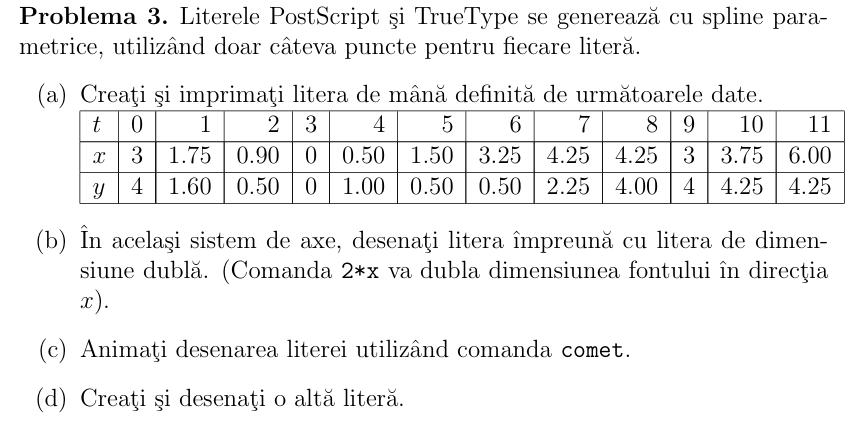

%% Functii auxiliare pentru spline cubic natural

function coef = spline_coef_natural(x, f)
% SPLINE_COEF_NATURAL - Calculeaza coeficientii spline-ului cubic natural
% INPUT:
%   x - vectorul nodurilor (crescator)
%   f - valorile functiei in noduri
% OUTPUT:
%   coef - coeficientii [a, b, c, d] pentru fiecare polinom spline

    n = length(x);
    h = diff(x);
    A = zeros(n); rhs = zeros(n,1);

    A(1,1) = 1; A(end,end) = 1;
    for i = 2:n-1
        A(i,i-1) = h(i-1);
        A(i,i)   = 2*(h(i-1) + h(i));
        A(i,i+1) = h(i);
        rhs(i)   = 3*((f(i+1)-f(i))/h(i) - (f(i)-f(i-1))/h(i-1));
    end

    c = A \ rhs;

    a = f(1:end-1);
    b = zeros(n-1,1);
    d = zeros(n-1,1);
    for i = 1:n-1
        b(i) = (f(i+1)-f(i))/h(i) - h(i)*(2*c(i)+c(i+1))/3;
        d(i) = (c(i+1)-c(i))/(3*h(i));
    end

    coef = [a(:), b, c(1:end-1), d];
end

function val = spline_eval_custom(x, coef, xx)
% SPLINE_EVAL_CUSTOM - Evalueaza spline cubic natural in punctele xx
% INPUT:
%   x     - noduri
%   coef  - coeficientii spline-ului
%   xx    - puncte de evaluare
% OUTPUT:
%   val   - valorile spline-ului in xx

    val = zeros(size(xx));
    n = length(x);

    for j = 1:length(xx)
        idx = find(xx(j) >= x(1:end-1) & xx(j) <= x(2:end), 1, 'first');
        if isempty(idx)
            idx = (xx(j) < x(1)) * 1 + (xx(j) > x(end)) * (n - 1);
        end
        dx = xx(j) - x(idx);
        a = coef(idx,1); b = coef(idx,2);
        c = coef(idx,3); d = coef(idx,4);
        val(j) = a + b*dx + c*dx^2 + d*dx^3;
    end
end

%% Subpunct (a) - Deseneaza litera originala
function deseneazaLiteraOriginala()
    T = 0:11;
    X = [3 1.75 0.90 0 0.50 1.50 3.25 4.25 4.25 3 3.75 6.00];
    Y = [4 1.60 0.50 0 1.00 0.50 0.50 2.25 4.00 4 4.25 4.25];
    
    coef_x = spline_coef_natural(T, X);
    coef_y = spline_coef_natural(T, Y);
    tt = linspace(T(1), T(end), 300);
    x_interp = spline_eval_custom(T, coef_x, tt);
    y_interp = spline_eval_custom(T, coef_y, tt);

    figure;
    plot(X, Y, 'ko', 'MarkerSize', 6, 'LineWidth', 1.5); hold on;
    plot(x_interp, y_interp, 'b-', 'LineWidth', 2);
    title('(a) Litera originala desenata cu spline cubic');
    legend('Puncte', 'Curbă spline');
    axis equal; grid on;
end

%% Subpunct (b) - Litera originala si versiunea dublata
function deseneazaLiteraScalata()
    T = 0:11;
    X = [3 1.75 0.90 0 0.50 1.50 3.25 4.25 4.25 3 3.75 6.00];
    Y = [4 1.60 0.50 0 1.00 0.50 0.50 2.25 4.00 4 4.25 4.25];

    Xs = 2 * X;
    Ys = 2 * Y;
    coef_x = spline_coef_natural(T, X);
    coef_y = spline_coef_natural(T, Y);
    coef_xs = spline_coef_natural(T, Xs);
    coef_ys = spline_coef_natural(T, Ys);
    tt = linspace(T(1), T(end), 300);
    x1 = spline_eval_custom(T, coef_x, tt);
    y1 = spline_eval_custom(T, coef_y, tt);
    x2 = spline_eval_custom(T, coef_xs, tt);
    y2 = spline_eval_custom(T, coef_ys, tt);

    figure;
    plot(x1, y1, 'b-', 'LineWidth', 2); hold on;
    plot(x2, y2, 'r--', 'LineWidth', 2);
    plot(X, Y, 'bo'); plot(Xs, Ys, 'ro');
    title('(b) Litera si versiunea dublata');
    legend('Originala', 'Scalata', 'Puncte orig.', 'Puncte scalate');
    axis equal; grid on;
end

%% Subpunct (c) - Animatie cu comet
function animaLitera()
    T = 0:11;
    X = [3 1.75 0.90 0 0.50 1.50 3.25 4.25 4.25 3 3.75 6.00];
    Y = [4 1.60 0.50 0 1.00 0.50 0.50 2.25 4.00 4 4.25 4.25];
    coef_x = spline_coef_natural(T, X);
    coef_y = spline_coef_natural(T, Y);
    tt = linspace(T(1), T(end), 300);
    x = spline_eval_custom(T, coef_x, tt);
    y = spline_eval_custom(T, coef_y, tt);

    figure;
    comet(x, y);
    title('(c) Animatie desenare litera');
    axis equal;
end

%% Subpunct (d) - Alta litera (ex: "J")
function deseneazaAltaLitera()
    Tx = 0:5;
    Xj = [5 4 3 2.5 2 2.5];
    Yj = [5 4 3 2 1 0];
    coef_x = spline_coef_natural(Tx, Xj);
    coef_y = spline_coef_natural(Tx, Yj);
    tt = linspace(Tx(1), Tx(end), 300);
    xj = spline_eval_custom(Tx, coef_x, tt);
    yj = spline_eval_custom(Tx, coef_y, tt);

    figure;
    plot(Xj, Yj, 'ms', 'MarkerFaceColor', 'm'); hold on;
    plot(xj, yj, 'm-', 'LineWidth', 2);
    title('(d) Alta litera "J" desenata cu spline cubic');
    axis equal; grid on;
end

% executaProblema3.m
clc; clear; close all;

disp('--- Problema 3: Litere cu spline cubic natural ---');

--- Problema 3: Litere cu spline cubic natural ---



disp('(a) Desenam litera originala...');

(a) Desenam litera originala...


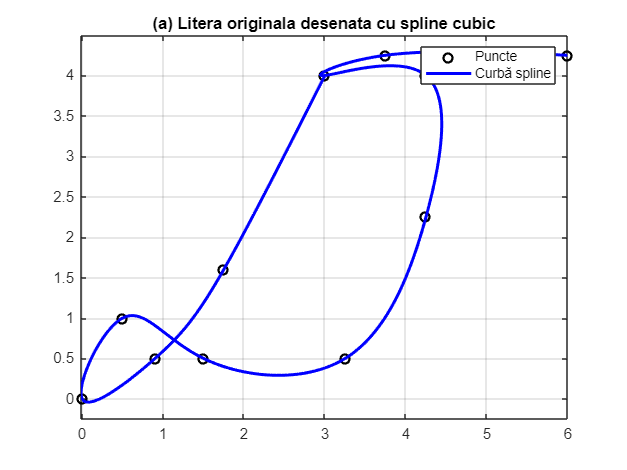

deseneazaLiteraOriginala();


disp('(b) Adaugam versiunea dublata...');

(b) Adaugam versiunea dublata...


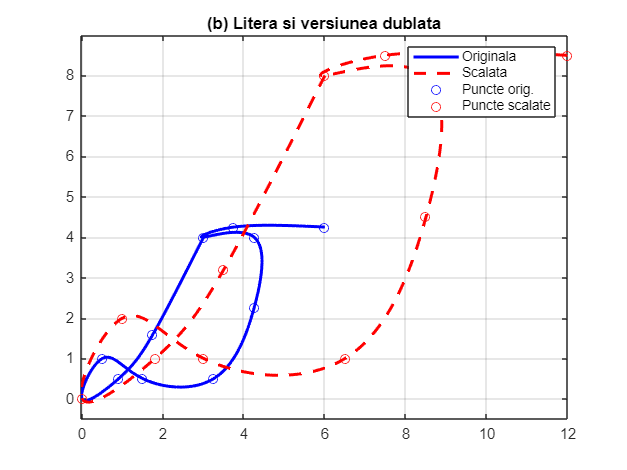

deseneazaLiteraScalata();


disp('(c) Animam litera...');

(c) Animam litera...


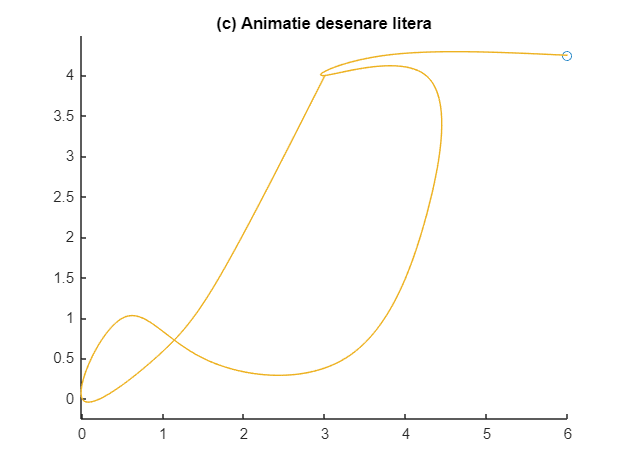

animaLitera();


disp('(d) Desenam alta litera ("J")...');

(d) Desenam alta litera ("J")...


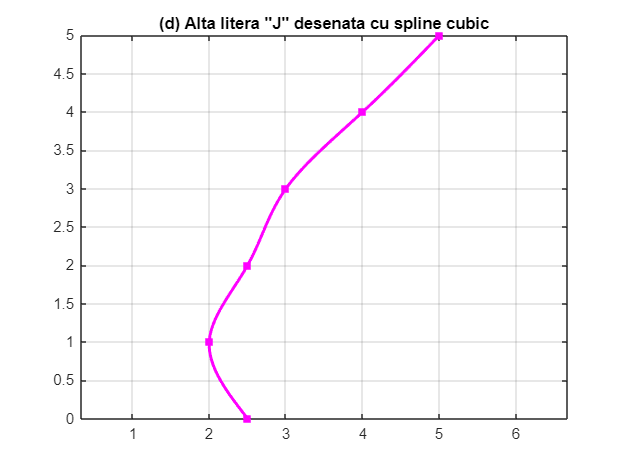

deseneazaAltaLitera();